# **MiniQuiz Lec 11 [ALL CORRECT]**

## Q1 [CORRECT]

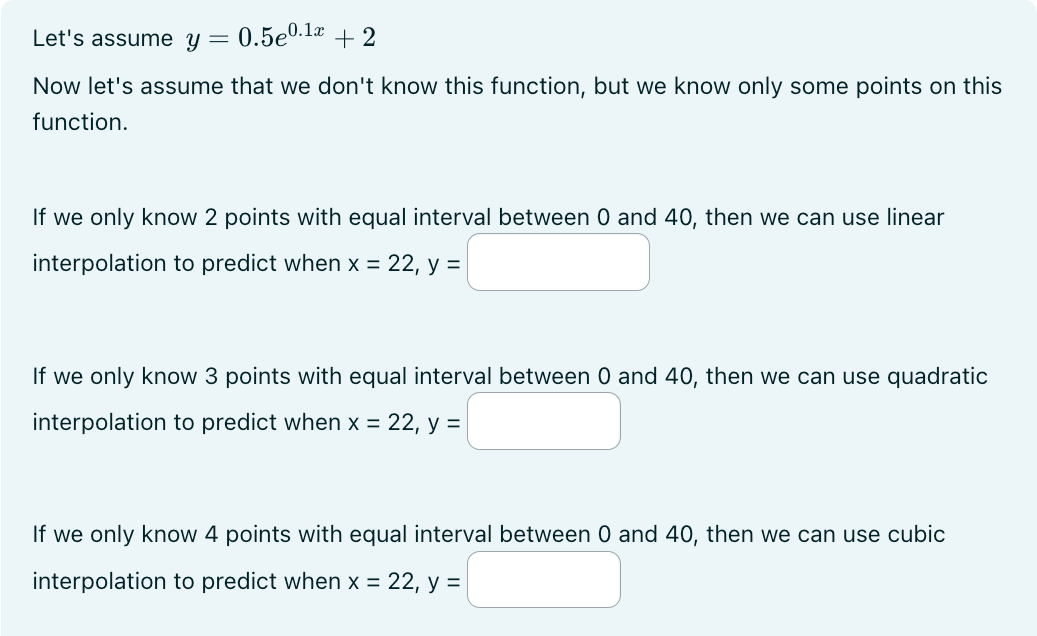

xtest = 22;
xx = 0:1:40;
yy = 0.5 * exp(0.1.*xx) + 2;

**Linear Interpolation**

xx1 = linspace(0, 40, 2);
y1 = 0.5 * exp(0.1.*xx1) + 2;
p1 = polyfit(xx1, y1, 1);
ypred1 = polyval(p1, xtest)

ypred1 = 17.2395

plot(xx, yy, '-', xtest, ypred1, 'o', xx1, y1, 'r--');

**Quadratic Interpolation**

xx2 = linspace(0, 40, 3);
y2 = 0.5 * exp(0.1.*xx2) + 2;
p2 = polyfit(xx2, y2, 2);
ypred2 = polyval(p2, xtest)

ypred2 = 7.1365

plot(xx, yy, '-', xtest, ypred2, 'o', xx2, y2, 'r--');

**Cubic Interpolation**

xx3 = linspace(0, 40, 4);
y3 = 0.5 * exp(0.1.*xx3) + 2;
p3 = polyfit(xx3, y3, 3);
ypred3 = polyval(p3, xtest)

ypred3 = 6.2153

plot(xx, yy, '-', xtest, ypred3, 'o', xx3, y3, 'r--');

## Q2 [CORRECT]

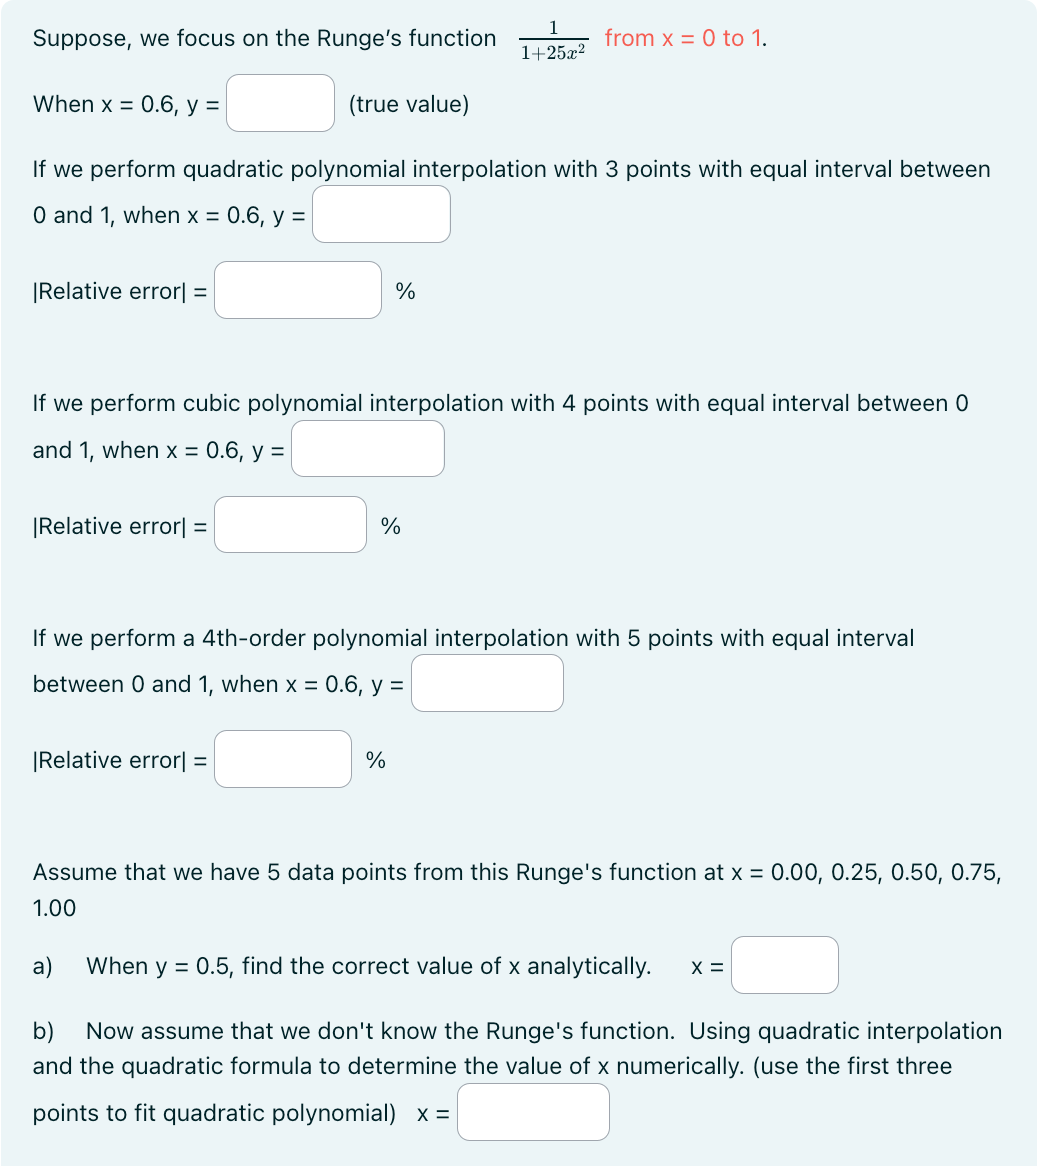

xtest = 0.6;
xx = 0:0.01:1;
yy = 1 ./ (1 + 25.*xx.^2);
ytrue = 1 ./ (1 + 25.*xtest.^2)

ytrue = 0.1000

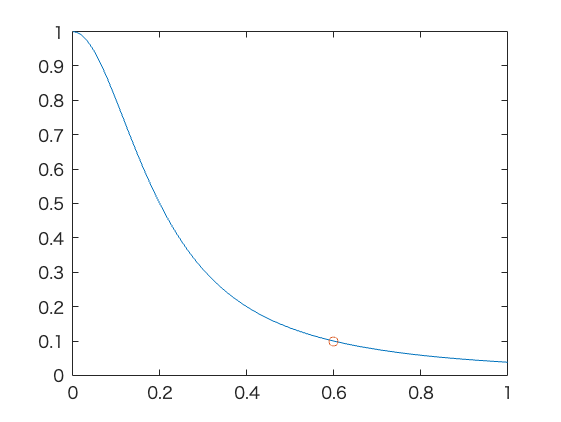

plot(xx, yy, '-', xtest, ytrue, 'o')

**Quadratic**

xx2 = linspace(0, 1, 3);
yy2 = 1 ./ (1 + 25.*xx2.^2);
p2 = polyfit(xx2, yy2, 2);
ypred2 = polyval(p2, xtest)

ypred2 = 0.0570

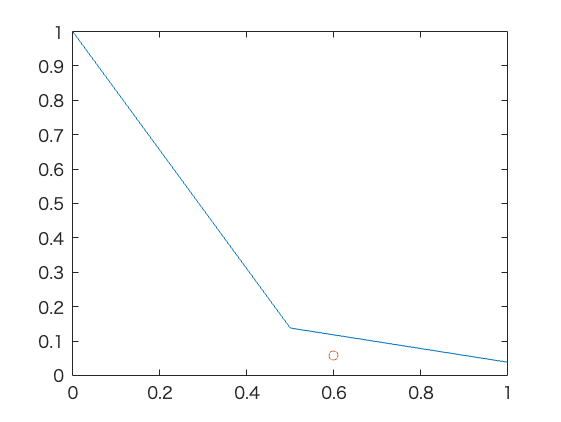

plot(xx2, yy2, '-', xtest, ypred2, 'o')

errq = abs((ytrue - ypred2) / ytrue) * 100

errq = 42.9708

**Cubic**

xx3 = linspace(0, 1, 4);
yy3 = 1 ./ (1 + 25.*xx3.^2);
p3 = polyfit(xx3, yy3, 3);
ypred3 = polyval(p3, xtest)

ypred3 = 0.0947

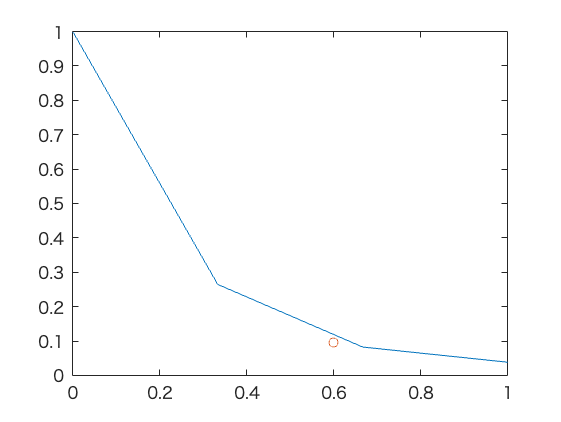

plot(xx3, yy3, '-', xtest, ypred3, 'o')

errc = abs((ytrue - ypred3) / ytrue) * 100

errc = 5.3302

**4th-order**

xx4 = linspace(0, 1, 5);
yy4 = 1 ./ (1 + 25.*xx4.^2);
p4 = polyfit(xx4, yy4, 4);
ypred4 = polyval(p4, xtest)

ypred4 = 0.0962

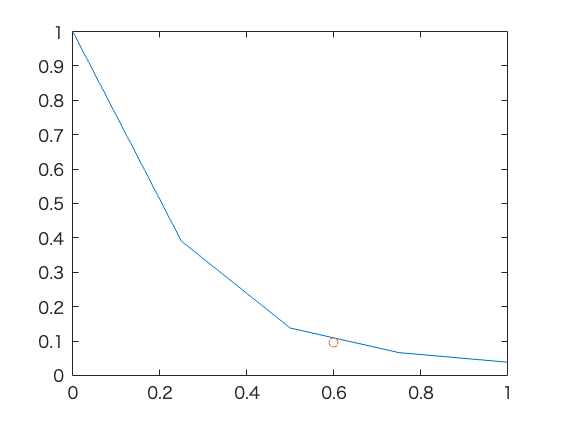

plot(xx4, yy4, '-', xtest, ypred4, 'o')

err4th = abs((ytrue - ypred4) / ytrue) * 100

err4th = 3.8120

**Inverse**

a)

xxinv = [0.00, 0.25, 0.50, 0.75, 1.00];
ytest = 0.5;
% xinvtrue = sqrt(((1/ytest)-1) * (1/25)) % 0.2000
xinvtrue = sqrt( (1-ytest) / (25*ytest) ) % 0.2000

xinvtrue = 0.2000

b)

xxinv2 = [0.00, 0.25, 0.50];
yyinv2 = 1 ./ (1 + 25.*xxinv2.^2);
pinv2 = polyfit(xxinv2, yyinv2, 2)

pinv2 =     2.8595   -3.1539    1.0000


c = pinv2(3) - ytest;
b = pinv2(2);
a = pinv2(1);
x1 = (-b + sqrt(b^2 - (4*a*c))) / (2*a)

x1 = 0.9110

x2 = (-b - sqrt(b^2 - (4*a*c))) / (2*a)

x2 = 0.1919

% ans = x2 = 0.1919